%paper parameters
duty_cycle = 0.01; %duty cycle toi da
r = 20; %ban kinh
area = pi * r^2; %dien tich 
intensity_GW = 0.05; %gia tri intensity fucntion cua GW
intensity_ED = 5; %gia tri intensity function cua ED
BW = 125000;
NF = 6 ; %Noise figure
N_gauss = 10^((-174+NF+10*log10(BW))/10)/(10^3); %gauss addictive no ise variance (W)
Power = (10^(1.9))/(10^3);
lambda = 34.5 * 10 ^ (-5); %wave length in km
eta = 3; %theo quy uoc
d = 0:0.2:8;
desired_SIR = 1.259 %w theo quy uoc cua de bai

desired_SIR = 1.2590

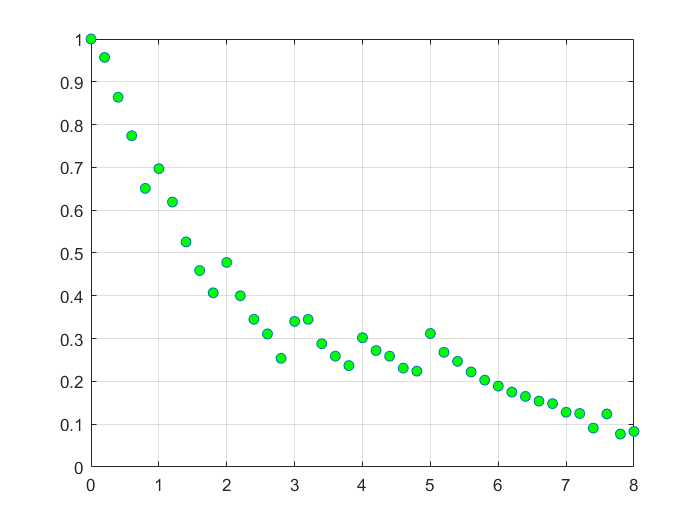

    %Mo phong
    rng(1); 
    
    %----------------------------------------------------
    %Model
    ED_number = poissrnd(area*intensity_ED); %so luong ED trong disc tuan theo luat poisson
    GW_number = poissrnd(area*intensity_GW); %so luong GW trong disc tuan theo luat poisson
    
    %cac tham so 1 ung voi ED, 2 ung voi GW
    theta1 = 2*pi*(rand(ED_number,1));
    rho1 = r*sqrt(rand(ED_number,1));
    [xx1,yy1] = pol2cart(theta1,rho1);
            
            
    theta2 = 2*pi*(rand(GW_number,1));
    rho2 = r*sqrt(rand(GW_number,1));
    [xx2,yy2] = pol2cart(theta2,rho2);
            
    %tinh khoang cach tu cac ED toi GW
            
            
    dis = zeros(length(xx2),length(xx1)); %mang luu khoang cach tu cac ED toi cac GW
    hold off
            
    %Tinh khoang cach tu cac ED toi cac GW
    for ii1 = 1:length(xx1)
        dis(:,ii1) = sqrt((xx1(ii1)-xx2).^2+(yy1(ii1)-yy2).^2);
    end
    
    dis_ED = pdist2([xx2(1),yy2(1)], [xx1(2:end),yy1(2:end)]);
    smallest_dis = min(dis); %lay ra cac khoang cach nho nhat cua tung ED toi GW
    
    %Dat cac gia tri SF cho cac ED
    SF_value = zeros(1,ED_number);%Mang chua gia tri cac SF cua cac ED
    for i = 1:length(SF_value)
        SF_value(i) = generate_SF(smallest_dis(i));
    end
    
    %----------------------------------------------------
    P_sim = zeros(size(d)); %Xac suat P mo phong theo cong thuc (6) voi moi khoang cach
    P_SIR = zeros(size(d)); %Xac suat P mo phong theo cong thuc (7) voi moi khoang cach
    %Bat dau vong lap
    for ii2 = 1:length(d)
        
        N_trial = 1000 ; %So lan mo phong ung voi moi gia tri khoang cach
        check_P_sim_vt = zeros(1,N_trial); %Vector luu nhung lan dat gia tri mo phong theo P
        check_P_SIR_vt = zeros(1,N_trial); %Vector luu nhung lan dat gia tri mo phong SIR
        
        for trial = 1:N_trial
            %----------------------------------------------------
            channel_gain = exprnd(1);       %channel gain between an ED and a GW
            desired_qSF = set_qSF(d(ii2));  %dat qSF cho cac node ngau nhien
            
            %----------------------------------------------------
            %Tinh SNR 00
            path_loss_attenuated = (lambda/(4*pi*d(ii2)))^eta;
            qSF = 10^(set_qSF(d(ii2))/10);
            SNR_00 = (Power*(abs(channel_gain)^2)*path_loss_attenuated)/N_gauss;
            
            %Kiem tra dieu kien (6)
            if SNR_00 >= qSF
                check_P_sim_vt(trial) = 1;
            else
                check_P_sim_vt(trial) = 0;
            end
            
            %----------------------------------------------------
            %Tinh SIR 00
            %Kiem tra dieu kien ED j dang truyen cung SF voi ED 0
            X = zeros(1,ED_number-1); %Mang luu cac gia tri cua X 0k
            channal_gain_k = zeros(1,ED_number-1);%Mang luu cac gia tri channal gain bat ki 0k
            path_loss_attenuated_k = zeros(1,ED_number-1);%Mang luu cac gia tri g(d0k)
            
            %Coi ED 0 la diem nhin. ta tinh khoang cach tu ED 0 toi cac ED
            %con lai
            
            ch_gain = exprnd(1,1,length(channal_gain_k));
            path_loss_attenuated_k = (lambda./(4.*pi.*dis_ED)).^eta;
            
            %Kiem tra dieu kien trung SF giua ED k bat ki voi ED 0
            SF_ED0 = generate_SF(d(ii2));
            for ii7 = 1:length(dis_ED)
                if SF_value(ii7) == SF_ED0
                    X(ii7) = 1;
                else 
                    X(ii7) = 0;
                end
            end
            
            
            %Tinh I_0
            I_0 = sum(Power.*X.*((abs(ch_gain)).^2).*path_loss_attenuated_k);
            
            %Tinh SIR_00
            SIR_00 = (Power*((abs(channel_gain))^2)*path_loss_attenuated)/I_0;
            
            %Kiem tra dieu kien SIR
            if SIR_00 >= desired_SIR
                check_P_SIR_vt(trial) = 1;
            else
                check_P_SIR_vt(trial) = 0;
            end
            
        end
        P_sim(ii2) = sum(check_P_sim_vt)/N_trial;
        P_SIR(ii2) = sum(check_P_SIR_vt)/N_trial;
    end
    
    %----------------------------------------------------
    
    scatter(xx2,yy2,1,'black')
    axis square;
    
    %%Theory plot
    figure
    plot(d,P_sim,'Marker','o','Linestyle','none','MarkerFaceColor','g');
    grid on 

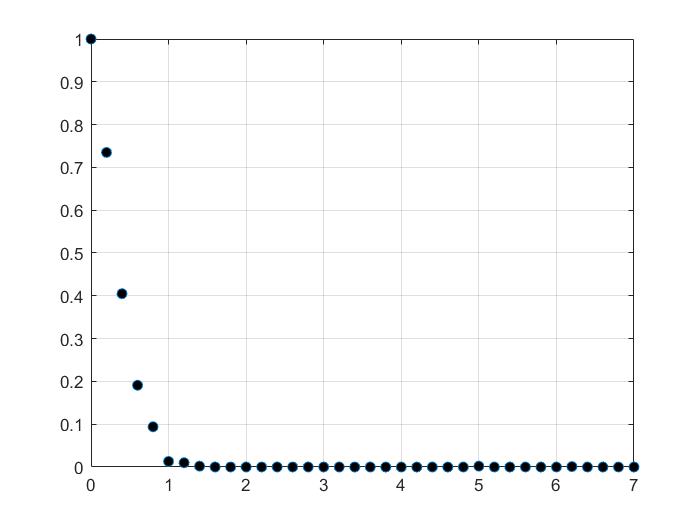

    
    
    %%Figure 3
    figure 
    plot(d,P_SIR,'Marker','o','LineStyle','none','MarkerFaceColor','k');
    axis([0 7 0 1])
    grid on

function op = set_qSF(l)
    if (0<=l) && (l<1)
        op = -6;
    elseif (l>=1) && (l<2)
        op = -9;
    elseif (l>=2) && (l<3)
        op = -12;
    elseif (l>=3) && (l<4)
        op = -15;
    elseif (l>=4) && (l<5)
        op = -17.5;
    else
        op = -20;
    end
end

function op = generate_SF(l)
    if (0<=l) && (l<1)
        op = 7;
    elseif (l>=1) && (l<2)
        op = 8;
    elseif (l>=2) && (l<3)
        op = 9;
    elseif (l>=3) && (l<4)
        op = 10;
    elseif (l>=4) && (l<5)
        op = 11;
    else
        op = 12;
    end
end